# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 23-May-2022 18:26:26

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = imageInputLayer([512 512 1],"Name","imageinput");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_1","Padding","same")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([5 5],"Name","maxpool_1","Padding","same")
    transposedConv2dLayer([3 3],32,"Name","transposed-conv_2","Cropping","same")
    reluLayer("Name","relu_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","conv_3","Padding","same")
    reluLayer("Name","relu_3")
    maxPooling2dLayer([5 5],"Name","maxpool_3","Padding","same")
    transposedConv2dLayer([3 3],32,"Name","transposed-conv_1","Cropping","same")
    reluLayer("Name","relu_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","conv_2","Padding","same")
    reluLayer("Name","relu_2")
    averagePooling2dLayer([5 5],"Name","avgpool2d_1","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_4","Padding","same")
    reluLayer("Name","relu_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(3,"Name","depthcat_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","conv_6","Padding","same")
    reluLayer("Name","relu_8")
    averagePooling2dLayer([5 5],"Name","avgpool2d_2","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_8","Padding","same")
    reluLayer("Name","relu_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","conv_7","Padding","same")
    reluLayer("Name","relu_9")
    maxPooling2dLayer([5 5],"Name","maxpool_4","Padding","same")
    transposedConv2dLayer([3 3],32,"Name","transposed-conv_3","Cropping","same")
    reluLayer("Name","relu_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_5","Padding","same")
    reluLayer("Name","relu_7")
    maxPooling2dLayer([5 5],"Name","maxpool_2","Padding","same")
    transposedConv2dLayer([3 3],32,"Name","transposed-conv_4","Cropping","same")
    reluLayer("Name","relu_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","depthcat_2")
    convolution2dLayer([3 3],2,"Name","conv_9","Padding","same")
    maxPooling2dLayer([2 2],"Name","maxpool_5","Padding","same")
    softmaxLayer("Name","softmax")
    pixelClassificationLayer("Name","pixel-class")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"imageinput","conv_1");
lgraph = connectLayers(lgraph,"imageinput","conv_3");
lgraph = connectLayers(lgraph,"imageinput","conv_2");
lgraph = connectLayers(lgraph,"relu_4","depthcat_1/in2");
lgraph = connectLayers(lgraph,"relu_5","depthcat_1/in1");
lgraph = connectLayers(lgraph,"relu_6","depthcat_1/in3");
lgraph = connectLayers(lgraph,"depthcat_1","conv_6");
lgraph = connectLayers(lgraph,"depthcat_1","conv_7");
lgraph = connectLayers(lgraph,"depthcat_1","conv_5");
lgraph = connectLayers(lgraph,"depthcat_1","depthcat_2/in4");
lgraph = connectLayers(lgraph,"relu_12","depthcat_2/in3");
lgraph = connectLayers(lgraph,"relu_10","depthcat_2/in2");
lgraph = connectLayers(lgraph,"relu_11","depthcat_2/in1");

## Plot Layers

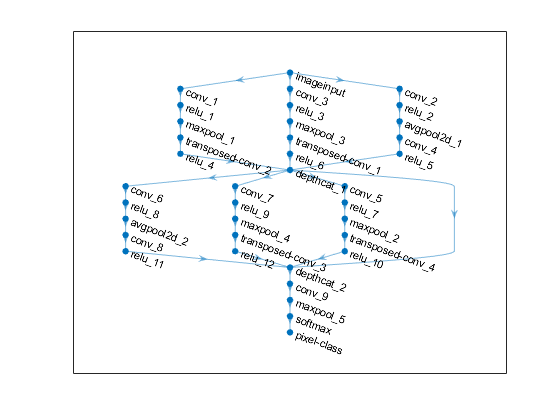

plot(lgraph);